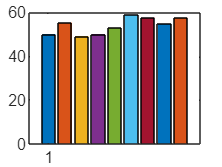

30 70 60 80 30 50 30 40 40 70 50 40 50 30 50 50 60 60 60 50 60 50 40 60 50 70 50 30 70 70 40 80 80 30 60 50 40 20 40 60 30 50 50 50 70 50 70 60 50 40 70 50 50 50 60 70 30 40 50 20 50 40 20 30 50 20 70 70 80 30 70 40 50 60 40 60 20 30 50 60 70 60 60 30 40 60 60 30 50 30 60 20 80 40 70 60 20 60 30 70 60 50 70 70 50 50 30 20 50 50 50 60 70 60 40 40 50 40 40 50 50 60 70 60 30 80 40 60 70 40 50 50 70 80 50 50 70 50 70 40 50 70 70 70 70 60 60 50 60 30 30 60 50 50 70 70 50 60 50 70 70 40 70 30 60 70 40 60 60 70 60 70 70 40 50 60 50 70 60 50 70 30 50 60 70 30 60 50 40 60 50 60 30 40 80 50 60 60 50 80 50 50 30 40 60 50 30 70 60 60 60 60 40 70 40 30 80 60 60 60 60 20 50 50 40 40 40 40 60 50 50 40 20 70 40 50 60 60 40 50 40 50 70 50 40 30 50 40 40 40 60 60 50 50 20 30 60 60 50 50 70 40 20 40 50 60 30 70 70 50 60 60 30 80 40 30 60 50 60 10 30 50 40 60 70 60 40 60 40 40 40 40 80 50 60 50 70 50 30 40 40 30 50 80 50 50 40 70 60 70 50 60 90 50 60 40 30 40 70 30 60 70 60 50 60 20 50 10 50 50 30 60 50 3

clear;
clf;
%load common data
load("ChanName.mat");
load('Pair54.mat');
load('timeRawTrace.mat')

%extract the Person_X data
for i = 1:4
    rawTracePerson = sprintf("Person%d\\rawTracePerson%d.mat",i,i);
    OSPerson = sprintf("Person%d\\OSPerson%d.mat",i,i);

    rawTracePerson_info = whos('-file', rawTracePerson);
    rawTracePerson_name = {rawTracePerson_info.name};
    OSPerson_info = whos('-file',OSPerson);
    OSPerson_name = {OSPerson_info.name};
    
    load(rawTracePerson);
    load(OSPerson);
    for j=1:length(rawTracePerson_name)
        eval(sprintf("%s_P%d = %s;",rawTracePerson_name{j},i,rawTracePerson_name{j}));
    end
  
    for j=1:length(OSPerson_name)
        eval(sprintf("%s_P%d = %s;",OSPerson_name{j},i,OSPerson_name{j}));
    end
    
end


num = 100;
for t = 1:9
    for n = 1:num
    ind = 0.9;
    %OS_interest1 = reshape(OS_P1(16:31,5:14,:,t),[],40);
    OS_interest1 = reshape(OS_P1(16:31,:,:,t),[],40);
    [ndata1,D1] = size(OS_interest1');
    R1 = randperm(ndata1);
    trainData1 = OS_interest1(:,R1(1:ind*40));
    trainLabel1 = Track_P1(R1(1:ind*40));
    testDate1 = OS_interest1(:,R1(ind*40+1:end));
    testLabel1 = Track_P1(R1(ind*40+1:end));

    %Person_2
    %4-8 OS_interest2 = reshape(OS_P2(16:31,5:14,:,2),[],10);
    OS_interest2 = reshape(OS_P2(16:31,:,:,t),[],10);
    [ndata2,D2] = size(OS_interest2');
    R2 = randperm(ndata2);
    trainData2 = OS_interest2(:,R2(1:ind*10));
    trainLabel2 = Track_P2(R2(1:ind*10));
    testDate2 = OS_interest2(:,R2(ind*10+1:end));
    testLabel2 = Track_P2(R2(ind*10+1:end));

    %Person_3
    %OS_interest3 = reshape(OS_P3(16:31,5:14,:,2),[],40);
    OS_interest3 = reshape(OS_P3(16:31,:,:,t),[],40);
    [ndata3,D3] = size(OS_interest3');
    R3 = randperm(ndata3);
    trainData3 = OS_interest3(:,R1(1:ind*40));
    trainLabel3 = Track_P3(R3(1:ind*40));
    testDate3 = OS_interest3(:,R3(ind*40+1:end));
    testLabel3 = Track_P3(R3(ind*40+1:end));

    %Person_4
    %OS_interest4 = reshape(OS_P4(16:31,5:14,:,2),[],10);
    OS_interest4 = reshape(OS_P4(16:31,:,:,t),[],10);
    [ndata4,D4] = size(OS_interest4');
    R4 = randperm(ndata4);
    trainData4 = OS_interest4(:,R4(1:ind*10));
    trainLabel4 = Track_P4(R4(1:ind*10));
    testDate4 = OS_interest4(:,R4(ind*10+1:end),:);
    testLabel4 = Track_P4(R4(ind*10+1:end));

    %aggregate the dataset
    trainData = horzcat(trainData1,trainData2,trainData3,trainData4);
    testData = [testDate1,testDate2,testDate3,testDate4];

    %aggregate the label
    trainLabel = horzcat(trainLabel1,trainLabel2,trainLabel3,trainLabel4);
    testLabel = [testLabel1,testLabel2,testLabel3,testLabel4];

    %<11=match=1,>10=nonmatch=0
    for i = 1:90
        if trainLabel(1,i) < 11;
            trainLabel(1,i) = 1;
        else
            trainLabel(1,i) = 0;
        end
    end

    for j = 1:10
        if testLabel(1,j) > 11;
            testLabel(1,j) = 1;
        else
            testLabel(1,j) = 0;
        end
    end

    %svm分类
    %model = fitcsvm(trainData',trainLabel','KernelFunction','linear');
    %model = fitcsvm(trainData',trainLabel');
    %model = fitcsvm(trainData',trainLabel','Standardize',true,'KernelFunction','RBF',...
    %'KernelScale','auto');
    %rbf
    model = fitcsvm(trainData',trainLabel','Standardize',true,'KernelFunction','RBF','KernelScale','auto');
    
    %自动优化超参数
    %model = fitcsvm(trainData',trainLabel','OptimizeHyperparameters','auto','HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'));
    % SVM网络预测
    [predict_label] = predict(model,testData');
    TrainingAccuracy  =   length(find(predict_label == testLabel'))/length(testLabel')*100;
    fprintf("%d ",TrainingAccuracy);
    %plot(TrainingAccuracy);
    accuracy(n) = TrainingAccuracy;
    end
accuracy_freq_direct = mean(accuracy);
variance = var(accuracy);
%fprintf("mean:%d var:%d",accuracy_freq_direct,variance);
bar(t,accuracy_freq_direct);
hold on
end            